# Two-Link Planar Robot Manipulator with Distributed Mass

## Clear all data

clc;
clear all;
close all;
clf; %Clear all figures

## Basic Definition

bar_mass = [1; 1]; % mass of bar in kg
bar_length = [1; 1]; %Length of bar in m
center_of_mass  = [0.45; 0.45];
moment_of_inertia = [0.084; 0.084];
initial_parameters = [30; 0; 45; 0]; % Initial degree (theta1, theta_dot_1, theta2, theta_dot_2) parameters of bar
initial_parameters = [deg2rad(initial_parameters(1,1)); deg2rad(initial_parameters(2,1)); deg2rad(initial_parameters(3,1)); deg2rad(initial_parameters(4,1))]; % Initial degree (thetha, thetha_dot) parameters of bar
applied_torque = [0; 0]; % Applied torque to the bar (T) 
% where T is applied wrt to +ve x axis
gravitational_acceleration = 9.81; %m/s2
graph_time = 10; % Time frame for plotting

## Symbolic Definition

syms g m1 m2 h1 h2 v1 v2 I1 I2 w1 w2 l1 l2 r1 r2 x1(t) x2(t) y1(t) y2(t) theta1(t) theta2(t) T1 T2 'real' % Creating Symbolic Variables

sympref('AbbreviateOutput',false);
sympref('MatrixWithSquareBrackets',true);
sympref('PolynomialDisplayStyle','ascend');

## Define Generalised Coordinates

q = sym('q',[2,1]);
q(1) = theta1;
q(2) = theta2;
q

$$q = \left[\begin{array}{c} \theta_{1}\left(t\right)\\ \theta_{2}\left(t\right) \end{array}\right]$$

dq = diff(q,t)

$$dq = \left[\begin{array}{c} \frac{\partial }{\partial t}\theta_{1}\left(t\right)\\ \frac{\partial }{\partial t}\theta_{2}\left(t\right) \end{array}\right]$$

## Defining Generalised Inputs

u = sym('u',[2,1]);
u(1) = T1;
u(2) = T2;
u

$$u = \left[\begin{array}{c} T_{1}\\ T_{2} \end{array}\right]$$

## Derive Lagrangian Function

PE = m1*g*h1 + m2*g*h2;
PE = subs(PE,[h1, h2],[r1*cos(theta1), l1*cos(theta1) + r2*cos(theta1 + theta2)])

$$PE = \left(\cos\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)\,r_{2}+\cos\left(\theta_{1}\left(t\right)\right)\,l_{1}\right)\,g\,m_{2}+\cos\left(\theta_{1}\left(t\right)\right)\,g\,m_{1}\,r_{1}$$

KE = (m1*(v1^2)/2) + (I1*(w1^2)/2) + (m2*(v2^2)/2) + (I2*(w2^2)/2);
KE = subs(KE,[v1, v2],[sqrt(diff(x1,t)^2 + diff(y1,t)^2), sqrt(diff(x2,t)^2 + diff(y2,t)^2)]);
KE = subs(KE,[x1,y1,w1,x2,y2,w2],[r1*sin(theta1), r1*cos(theta1), diff(theta1,t), l1*sin(theta1) + r2*sin(theta1 + theta2), l1*cos(theta1) + r2*cos(theta1 + theta2),diff(theta1 + theta2,t)])

$$KE = \frac{m_{2}\,\left({\left(r_{2}\,\cos\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)\,\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)+\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)+l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}+{\left(r_{2}\,\sin\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)\,\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)+\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)+l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}\right)}{2}+\frac{m_{1}\,\left({r_{1}}^{2}\,{\sin\left(\theta_{1}\left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}+{r_{1}}^{2}\,{\cos\left(\theta_{1}\left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}\right)}{2}+\frac{I_{1}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}}{2}+\frac{I_{2}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)+\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}}{2}$$

LE = KE - PE;
LE = simplify(LE)

$$LE = \frac{I_{1}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}}{2}+\frac{I_{2}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}}{2}+\frac{I_{2}\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}}{2}+I_{2}\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)+\frac{{l_{1}}^{2}\,m_{2}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}}{2}+\frac{m_{1}\,{r_{1}}^{2}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}}{2}+\frac{m_{2}\,{r_{2}}^{2}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}}{2}+\frac{m_{2}\,{r_{2}}^{2}\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}}{2}+m_{2}\,{r_{2}}^{2}\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)-g\,m_{2}\,r_{2}\,\cos\left(\theta_{1}\left(t\right)+\theta_{2}\left(t\right)\right)-g\,l_{1}\,m_{2}\,\cos\left(\theta_{1}\left(t\right)\right)-g\,m_{1}\,r_{1}\,\cos\left(\theta_{1}\left(t\right)\right)+l_{1}\,m_{2}\,r_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}+l_{1}\,m_{2}\,r_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)$$

## Derive Euler Lagrangian Equations

dLE_dq = jacobian(LE,q);
dLE_ddq = jacobian(LE,dq);
d_dLE_dtDdq = diff(dLE_ddq,t);
EU_eq1 = d_dLE_dtDdq(1,1) - dLE_dq(1,1) - u(1);
EU_eq2 = d_dLE_dtDdq(1,2) - dLE_dq(1,2) - u(2);
EU_eq1 = simplify(EU_eq1);
EU_eq2 = simplify(EU_eq2);
syms thethaddot1 thethaddot2 'real'
EU_eq1 = subs(EU_eq1,[diff(theta1,t,2), diff(theta2,t,2)],[thethaddot1, thethaddot2]);
EU_eq2 = subs(EU_eq2,[diff(theta1,t,2), diff(theta2,t,2)],[thethaddot1, thethaddot2]);

## Symbolic Solution to EL Equation

[thethaddot1, thethaddot2]=solve([EU_eq1, EU_eq2],[thethaddot1, thethaddot2])

## Defining State Space Matrix

syms x1(t) x2(t) x3(t) x4(t)
x = [x1;x2;x3;x4]

$$x(t) = \left[\begin{array}{c} x_{1}\left(t\right)\\ x_{2}\left(t\right)\\ x_{3}\left(t\right)\\ x_{4}\left(t\right) \end{array}\right]$$

%x(1) = theta1;
%x(2) = diff(theta1,t);
%x(3) = theta2;
%x(4) = diff(theta2,t);
thethaddot1 = subs(thethaddot1,[g, T1, m1, l1, r1, I1, T2, m2, l2, r2, I2,theta1, theta2, diff(theta1), diff(theta2)],[gravitational_acceleration, applied_torque(1,1), bar_mass(1,1), bar_length(1,1), center_of_mass(1,1), moment_of_inertia(1,1), applied_torque(2,1), bar_mass(2,1), bar_length(2,1), center_of_mass(2,1), moment_of_inertia(2,1), x1, x3, x2, x4])

$$thethaddot1 = -\frac{\frac{16301277\,\sin\left(x_{1}\left(t\right)\right)}{4000000}+\frac{5157\,\sin\left(x_{3}\left(t\right)\right)\,{x_{2}\left(t\right)}^{2}}{40000}+\frac{5157\,\sin\left(x_{3}\left(t\right)\right)\,{x_{4}\left(t\right)}^{2}}{40000}-\frac{79461\,\cos\left(x_{3}\left(t\right)\right)\,\sin\left(x_{1}\left(t\right)+x_{3}\left(t\right)\right)}{40000}+\frac{81\,\cos\left(x_{3}\left(t\right)\right)\,\sin\left(x_{3}\left(t\right)\right)\,{x_{2}\left(t\right)}^{2}}{400}+\frac{5157\,\sin\left(x_{3}\left(t\right)\right)\,x_{2}\left(t\right)\,x_{4}\left(t\right)}{20000}}{\frac{81\,{\cos\left(x_{3}\left(t\right)\right)}^{2}}{400}-\frac{1474329}{4000000}}$$

thethaddot2 = subs(thethaddot2,[g, T1, m1, l1, r1, I1, T2, m2, l2, r2, I2,theta1, theta2, diff(theta1), diff(theta2)],[gravitational_acceleration, applied_torque(1,1), bar_mass(1,1), bar_length(1,1), center_of_mass(1,1), moment_of_inertia(1,1), applied_torque(2,1), bar_mass(2,1), bar_length(2,1), center_of_mass(2,1), moment_of_inertia(2,1), x1, x3, x2, x4])

$$thethaddot2 = \frac{\frac{16301277\,\sin\left(x_{1}\left(t\right)\right)}{4000000}-\frac{22717017\,\sin\left(x_{1}\left(t\right)+x_{3}\left(t\right)\right)}{4000000}+\frac{14157\,\sin\left(x_{3}\left(t\right)\right)\,{x_{2}\left(t\right)}^{2}}{20000}+\frac{5157\,\sin\left(x_{3}\left(t\right)\right)\,{x_{4}\left(t\right)}^{2}}{40000}+\frac{256041\,\cos\left(x_{3}\left(t\right)\right)\,\sin\left(x_{1}\left(t\right)\right)}{40000}-\frac{79461\,\cos\left(x_{3}\left(t\right)\right)\,\sin\left(x_{1}\left(t\right)+x_{3}\left(t\right)\right)}{40000}+\frac{81\,\cos\left(x_{3}\left(t\right)\right)\,\sin\left(x_{3}\left(t\right)\right)\,{x_{2}\left(t\right)}^{2}}{200}+\frac{81\,\cos\left(x_{3}\left(t\right)\right)\,\sin\left(x_{3}\left(t\right)\right)\,{x_{4}\left(t\right)}^{2}}{400}+\frac{5157\,\sin\left(x_{3}\left(t\right)\right)\,x_{2}\left(t\right)\,x_{4}\left(t\right)}{20000}+\frac{81\,\cos\left(x_{3}\left(t\right)\right)\,\sin\left(x_{3}\left(t\right)\right)\,x_{2}\left(t\right)\,x_{4}\left(t\right)}{200}}{\frac{81\,{\cos\left(x_{3}\left(t\right)\right)}^{2}}{400}-\frac{1474329}{4000000}}$$

dx = [x2;
    thethaddot1;
    x4;
    thethaddot2]

$$dx(t) = \left[\begin{array}{c} x_{2}\left(t\right)\\ -\frac{\frac{16301277\,\sin\left(x_{1}\left(t\right)\right)}{4000000}+\frac{5157\,\sin\left(x_{3}\left(t\right)\right)\,{x_{2}\left(t\right)}^{2}}{40000}+\frac{5157\,\sin\left(x_{3}\left(t\right)\right)\,{x_{4}\left(t\right)}^{2}}{40000}-\frac{79461\,\cos\left(x_{3}\left(t\right)\right)\,\sin\left(x_{1}\left(t\right)+x_{3}\left(t\right)\right)}{40000}+\frac{81\,\cos\left(x_{3}\left(t\right)\right)\,\sin\left(x_{3}\left(t\right)\right)\,{x_{2}\left(t\right)}^{2}}{400}+\frac{5157\,\sin\left(x_{3}\left(t\right)\right)\,x_{2}\left(t\right)\,x_{4}\left(t\right)}{20000}}{\frac{81\,{\cos\left(x_{3}\left(t\right)\right)}^{2}}{400}-\frac{1474329}{4000000}}\\ x_{4}\left(t\right)\\ \frac{\frac{16301277\,\sin\left(x_{1}\left(t\right)\right)}{4000000}-\frac{22717017\,\sin\left(x_{1}\left(t\right)+x_{3}\left(t\right)\right)}{4000000}+\frac{14157\,\sin\left(x_{3}\left(t\right)\right)\,{x_{2}\left(t\right)}^{2}}{20000}+\frac{5157\,\sin\left(x_{3}\left(t\right)\right)\,{x_{4}\left(t\right)}^{2}}{40000}+\frac{256041\,\cos\left(x_{3}\left(t\right)\right)\,\sin\left(x_{1}\left(t\right)\right)}{40000}-\frac{79461\,\cos\left(x_{3}\left(t\right)\right)\,\sin\left(x_{1}\left(t\right)+x_{3}\left(t\right)\right)}{40000}+\frac{81\,\cos\left(x_{3}\left(t\right)\right)\,\sin\left(x_{3}\left(t\right)\right)\,{x_{2}\left(t\right)}^{2}}{200}+\frac{81\,\cos\left(x_{3}\left(t\right)\right)\,\sin\left(x_{3}\left(t\right)\right)\,{x_{4}\left(t\right)}^{2}}{400}+\frac{5157\,\sin\left(x_{3}\left(t\right)\right)\,x_{2}\left(t\right)\,x_{4}\left(t\right)}{20000}+\frac{81\,\cos\left(x_{3}\left(t\right)\right)\,\sin\left(x_{3}\left(t\right)\right)\,x_{2}\left(t\right)\,x_{4}\left(t\right)}{200}}{\frac{81\,{\cos\left(x_{3}\left(t\right)\right)}^{2}}{400}-\frac{1474329}{4000000}} \end{array}\right]$$

vars = [x1(t) x2(t) x3(t) x4(t)];
function_converter = odeFunction(dx, vars); % Converts symbolic function in Function
func_dx = @(t,x)function_converter(t,x);

## Solving Differential Equation to get thetha

tspan =[0 graph_time];
[t,state_space_matrix] = ode45(func_dx,tspan,initial_parameters);

## Calculating Link Positions

r_size = size(t);
position = zeros(r_size(1,1),4);
for i = 1:r_size(1,1)
    position(i,1) = bar_length(1,1)*sin(state_space_matrix(i,1));
    position(i,2) = bar_length(1,1)*cos(state_space_matrix(i,1));
    position(i,3) = position(i,1) + bar_length(2,1)*sin(state_space_matrix(i,1) + state_space_matrix(i,3));
    position(i,4) = position(i,2) + bar_length(2,1)*cos(state_space_matrix(i,1) + state_space_matrix(i,3));
    com_coordinates(i,1) = center_of_mass(1,1)*sin(state_space_matrix(i,1));
    com_coordinates(i,2) = center_of_mass(1,1)*cos(state_space_matrix(i,1));
    com_coordinates(i,3) = position(i,1) + center_of_mass(2,1)*sin(state_space_matrix(i,1) + state_space_matrix(i,3));
    com_coordinates(i,4) = position(i,2) + center_of_mass(2,1)*cos(state_space_matrix(i,1) + state_space_matrix(i,3));

end

## Animation

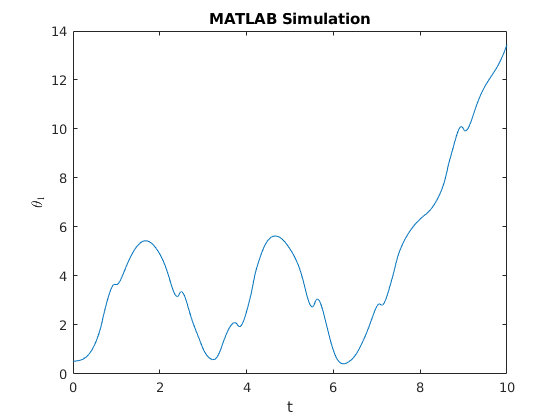

xAxisArrayXCoordinates = [-2 2];
xAxisArrayYCoordinates = [0 0];
yAxisArrayXCoordinates = [0 0];
yAxisArrayYCoordinates = [-2 2];
th = 0:pi/50:2*pi;
xunit = (bar_length(1,1) + bar_length(2,1)) * cos(th);
yunit = (bar_length(1,1) + bar_length(2,1)) * sin(th);
plot(t,state_space_matrix(:,1))
xlabel('t')
ylabel('${\theta_1}$', 'Interpreter','latex')
title('MATLAB Simulation')
saveas(gcf,'theta1.jpg')

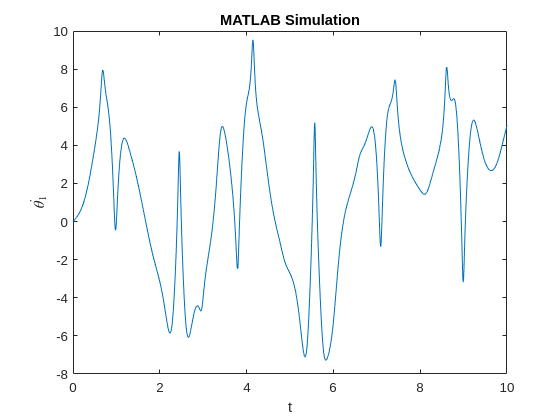

plot(t,state_space_matrix(:,2))
xlabel('t')
ylabel('$\dot{\theta_1}$', 'Interpreter','latex')
title('MATLAB Simulation')
saveas(gcf,'theta_dot_1.jpg')

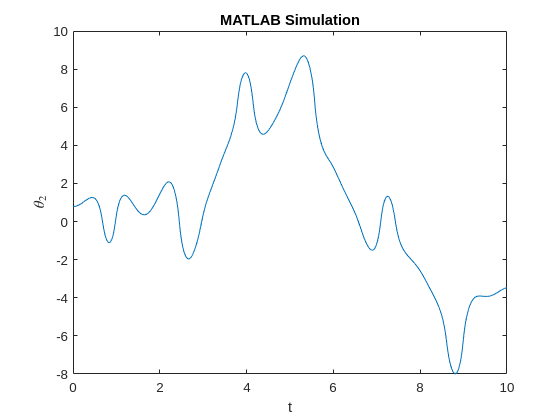

plot(t,state_space_matrix(:,3))
xlabel('t')
ylabel('${\theta_2}$', 'Interpreter','latex')
title('MATLAB Simulation')
saveas(gcf,'theta2.jpg')

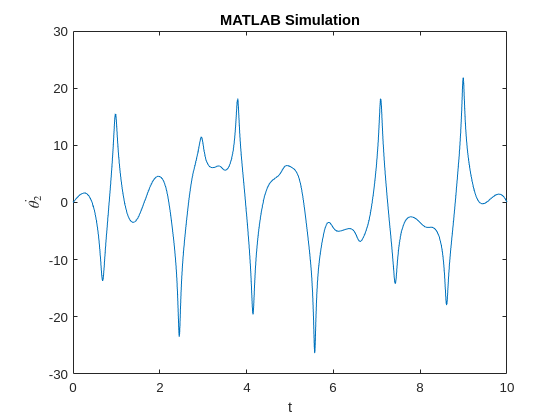

plot(t,state_space_matrix(:,4))
xlabel('t')
ylabel('$\dot{\theta_2}$', 'Interpreter','latex')
title('MATLAB Simulation')
saveas(gcf,'theta_dot_2.jpg')

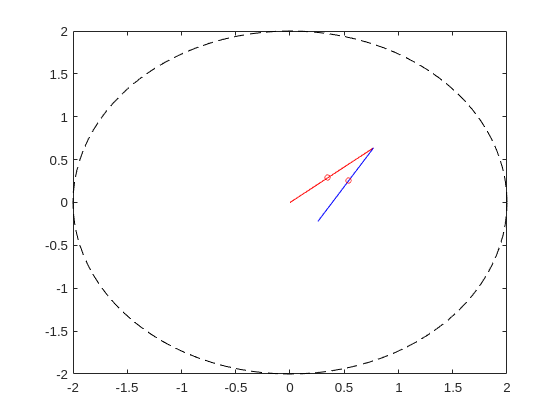

delete('MATLAB Simulation.avi');
animation = VideoWriter('MATLAB Simulation.avi');
open(animation);
for i = 1:1:r_size(1,1)
    %Plotting Graph
    link1XCoordinates = [0 position(i,1)];
    link1YCoordinates = [0 position(i,2)];
    link2XCoordinates = [position(i,1) position(i,3)];
    link2YCoordinates = [position(i,2) position(i,4)];
    plot(xunit, yunit,'k','LineStyle','--'); % Draw Circular Axes
    hold on;
    plot(link1XCoordinates, link1YCoordinates, 'red');
    plot(com_coordinates(i,1),com_coordinates(i,2),'-ro','MarkerSize',4);
    plot(link2XCoordinates, link2YCoordinates, 'blue');
    plot(com_coordinates(i,3),com_coordinates(i,4),'-ro','MarkerSize',4);
    frame = getframe(gcf);
    writeVideo(animation,frame);
    pause(0.1); % pause to see realtime animation. Given in seconds
    hold off;
end

close(animation);